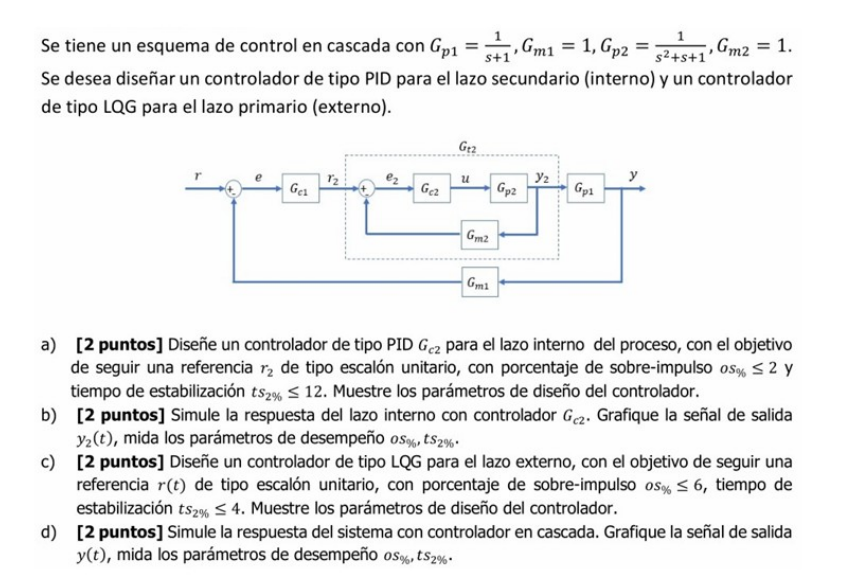

clear all
close all
clc
%%% LAZO INTERNO:
s=tf('s');
Gp2=1/(s^2+s+1)


Gp2 =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


Gm2=1

Gm2 = 1

Gc2=pidtune(Gp2,'PID')% Controlador


Gc2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 2.1, Ki = 1.19, Kd = 0.921
 
Continuous-time PID controller in parallel form.
Model Properties


Gt2=feedback(Gp2*Gc2,Gm2)


Gt2 =
 
    0.9206 s^2 + 2.095 s + 1.192
  ---------------------------------
  s^3 + 1.921 s^2 + 3.095 s + 1.192
 
Continuous-time transfer function.
Model Properties


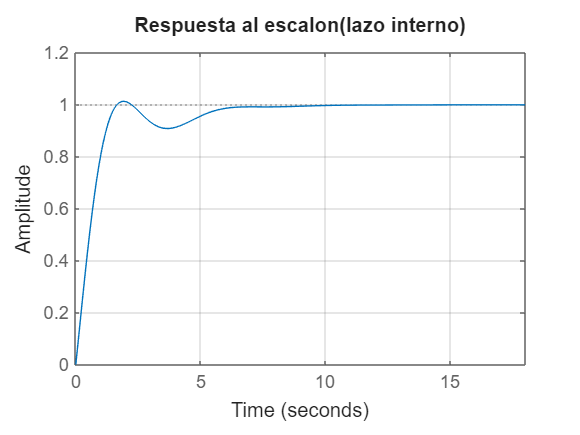

%% GRAFICAS DE LAZO INTERNO:
figure;
step(Gt2)
title('Respuesta al escalon(lazo interno)') ;
grid on ;

disp ('Desempeño') ;

Desempeño


stepinfo(Gt2)

ans = struct with fields:
         RiseTime: 1.1043
    TransientTime: 5.6705
     SettlingTime: 5.6705
      SettlingMin: 0.9087
      SettlingMax: 1.0135
        Overshoot: 1.3478
       Undershoot: 0
             Peak: 1.0135
         PeakTime: 1.9349


%%%% LAZO EXTERNO:
Gp1=1/(s+1)


Gp1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Gt2_1=Gt2*Gp1


Gt2_1 =
 
          0.9206 s^2 + 2.095 s + 1.192
  ---------------------------------------------
  s^4 + 2.921 s^3 + 5.016 s^2 + 4.287 s + 1.192
 
Continuous-time transfer function.
Model Properties


sp1=ss(Gt2_1)


sp1 =
 
  A = 
           x1      x2      x3      x4
   x1  -2.921  -2.508  -1.072  -0.596
   x2       2       0       0       0
   x3       0       2       0       0
   x4       0       0     0.5       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
           x1      x2      x3      x4
   y1       0  0.4603  0.5238   0.596
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


A1=sp1.A

A1 =    -2.9206   -2.5079   -1.0718   -0.5960
    2.0000         0         0         0
         0    2.0000         0         0
         0         0    0.5000         0


B1=sp1.B

B1 =      1
     0
     0
     0


C1=sp1.C

C1 =          0    0.4603    0.5238    0.5960


D1=sp1.D

D1 = 0

%%% LQG ESPACIO ESTADOS:

## **LQG con integrador:**

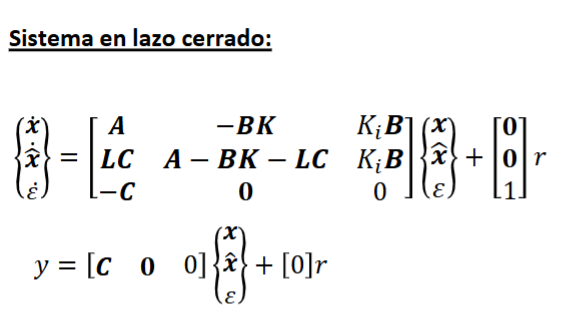

%% PARTE LQR
[n,~]=size(A1) %n=4 numero de estados

n = 4

**Matriz extendida**

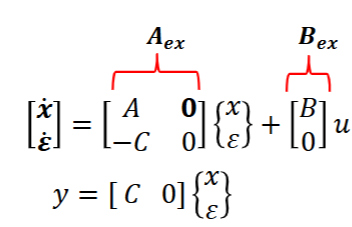

%Matriz extendida:
Ae=[A1 zeros(n,1);
    -C1 0]

Ae =    -2.9206   -2.5079   -1.0718   -0.5960         0
    2.0000         0         0         0         0
         0    2.0000         0         0         0
         0         0    0.5000         0         0
         0   -0.4603   -0.5238   -0.5960         0


Be=[B1;0]

Be =      1
     0
     0
     0
     0


Ce=[C1 0]

Ce =          0    0.4603    0.5238    0.5960         0


Q=diag([1,1,1,1,10]) % numero de terminos diagonal=n+1(Agregamos un estado mas (error))

Q =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0    10


R=[1]% Penaliza el esfuerzo de control

R = 1

[Kex P]=lqr(Ae,Be,Q,R)

Kex =     2.0127    3.7019    2.5841    2.4072   -3.1623


P =     2.0127    3.7019    2.5841    2.4072   -3.1623
    3.7019    8.3432    6.0227    5.5952   -7.8002
    2.5841    6.0227    5.1498    4.7731   -6.1512
    2.4072    5.5952    4.7731    6.6137   -6.4296
   -3.1623   -7.8002   -6.1512   -6.4296   15.9344


%% PARTE FILTRO KALMAN
G=eye(n) %n=4 estados del estimador

G =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Qn=eye(n)

Qn =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Rn=1

Rn = 1

[L,N]=lqe(A1,G,C1,Qn,Rn)

L =    -0.4780
    0.2120
    0.9559
    0.6532


N =     0.6109   -0.2388   -0.7877    0.0746
   -0.2388    0.8890   -0.0216   -0.3119
   -0.7877   -0.0216    2.4964   -0.5733
    0.0746   -0.3119   -0.5733    1.8407


%Calcuamos K y Ki
K=Kex(1:end-1)

K =     2.0127    3.7019    2.5841    2.4072


Ki=-Kex(end)

Ki = 3.1623

%%%% LAZO EXTERNO CERRADO
At1=[A1 -B1*K Ki*B1;
    L*C1 (A1-B1*K-L*C1) Ki*B1;
    -C1 zeros(1,n) 0]

At1 =    -2.9206   -2.5079   -1.0718   -0.5960   -2.0127   -3.7019   -2.5841   -2.4072    3.1623
    2.0000         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0
         0         0    0.5000         0         0         0         0         0         0
         0   -0.2200   -0.2504   -0.2849   -4.9333   -5.9898   -3.4055   -2.7184    3.1623
         0    0.0976    0.1111    0.1264    2.0000   -0.0976   -0.1111   -0.1264         0
         0    0.4400    0.5007    0.5697         0    1.5600   -0.5007   -0.5697         0
         0    0.3007    0.3421    0.3893         0   -0.3007    0.1579   -0.3893         0
         0   -0.4603   -0.5238   -0.5960         0         0         0         0         0


Bt1=[zeros(n,1); zeros(n,1); 1]

Bt1 =      0
     0
     0
     0
     0
     0
     0
     0
     1


Ct1=[C1 zeros(1,n) 0]

Ct1 =          0    0.4603    0.5238    0.5960         0         0         0         0         0


Dt1=0

Dt1 = 0

St1=ss(At1,Bt1,Ct1,Dt1)


St1 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8       x9
   x1   -2.921   -2.508   -1.072   -0.596   -2.013   -3.702   -2.584   -2.407    3.162
   x2        2        0        0        0        0        0        0        0        0
   x3        0        2        0        0        0        0        0        0        0
   x4        0        0      0.5        0        0        0        0        0        0
   x5        0    -0.22  -0.2504  -0.2849   -4.933    -5.99   -3.406   -2.718    3.162
   x6        0   0.0976   0.1111   0.1264        2  -0.0976  -0.1111  -0.1264        0
   x7        0     0.44   0.5007   0.5697        0     1.56  -0.5007  -0.5697        0
   x8        0   0.3007   0.3421   0.3893        0  -0.3007   0.1579  -0.3893        0
   x9        0  -0.4603  -0.5238   -0.596        0        0        0        0        0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   0
   x8   0
   x9   1
 
  C

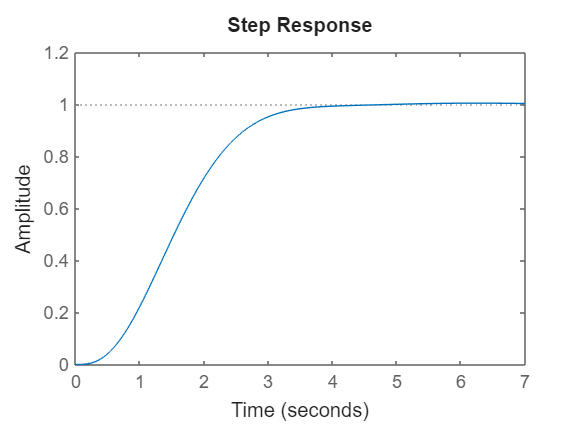

figure;
step(St1)